## 5.Repetição de ex1-3 com k=4:10

### 1. Criar Filtro de Bloom

file = fopen('wordlist-preao-20201103.txt','r');
palavras = textscan(file, '%s');
palavras_U1 = palavras{1};
fclose(file);
k_interval = 4:10;
n = 8000;
m=1000;
bloom_filters = cell(1,length(k_interval));
for k = k_interval
    B = inicializar(n);
    for i = 1:m
        B = adicionarElemento(B,palavras_U1{i},k);
    end
    bloom_filters{k-3} = B;
end

### 2.Verificar Falsos Negativos

for k = k_interval
    fake = 0;
    for i = 1:m
        bool = membro(bloom_filters{k-3},palavras_U1{i},k);
        if bool == false
            fake = fake+1;
        end
    end
end
if fake == 0
    fprintf('Não há falsos negativos, expectável né');
else
    fprintf('Existem %d falsos negativos, trolladinha do kazzio',fake);
end

Não há falsos negativos, expectável né

### 3.Procurar Falsos Positivos em um novo conjunto diferente do primeiro

fake_ps = zeros(1,length(k_interval));
fake_teo = zeros(1,length(k_interval));
fprintf('Probabilidade Prática de Falsos Positivos: \n')

Probabilidade Prática de Falsos Positivos: 


for k = k_interval
    fake_pose = 0;
    for i = 10001:20000
        if membro(bloom_filters{k-3},palavras_U1{i},k)
            fake_pose = fake_pose+1;
        end
    end
    fake_ps(k-3) = (fake_pose/10000)*100;
    pfp = (1-exp(-(k*m)/n))^k;
    fake_teo(k-3) = pfp*100;
    fprintf('k = %-2d - %-6.3f%s || Teórica - %.3f%s\n', k, (fake_pose/10000)*100, "%", pfp*100, "%");
end

k = 4  - 2.400 % || Teórica - 2.397%
k = 5  - 2.160 % || Teórica - 2.168%
k = 6  - 2.220 % || Teórica - 2.158%
k = 7  - 2.310 % || Teórica - 2.293%
k = 8  - 2.600 % || Teórica - 2.549%
k = 9  - 2.630 % || Teórica - 2.922%
k = 10 - 3.250 % || Teórica - 3.419%


##  Relação de Falsos Posititvos em função de k

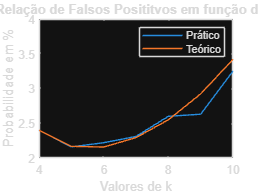

figure;
plot(k_interval,fake_ps);
hold on;
title('Relação de Falsos Posititvos em função de k');
plot(k_interval,fake_teo);
xlabel('Valores de k');
ylabel('Probabilidade em %');
legend('Prático','Teórico');
hold off;
[minY,index] = min(fake_ps);
axis([4 10 2 4]);


fprintf('O valor ótimo de k foi %d\n', k_interval(index));

O valor ótimo de k foi 5


fprintf('O valor ótimo teórico é %.3f\n', (n*log(2))/m);

O valor ótimo teórico é 5.545
